%%%%question 1%%%%%%%%
%(a)
A=[0 1;-1 0;-1 -1;1 1];
b=[0 0 1 1]';
p1=Polyhedron(A,b)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   4 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


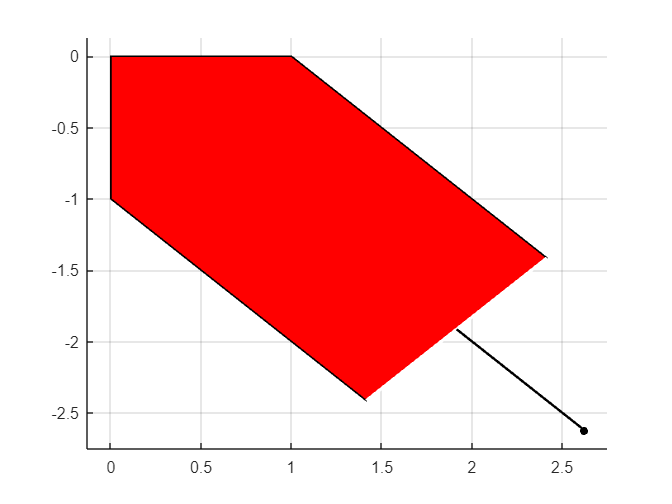

plot(p1)

V=[[0,0];[0,-1];[1,0]];
R=[1,-1];
p2=Polyhedron('V',V,'R',R)

Polyhedron in R^2 with representations:
    H-rep               : Unknown (call computeHRep() to compute)
    V-rep (redundant)   : Vertices   3 | Rays   1
Functions : none


plot(p2)

%%
% H-represetation is an intersection of a finite number of hyperplanes
% V-representation is an convex union of finite number of points


% (b)
A1=[0 1;1 0;0 -1;-1 0];
b1=[2;2;2;2];
A2=[-1 -1;1 1;1 -1;-1 1];
b2=[1;1;1;1];
P=Polyhedron(A1,b1)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   4 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


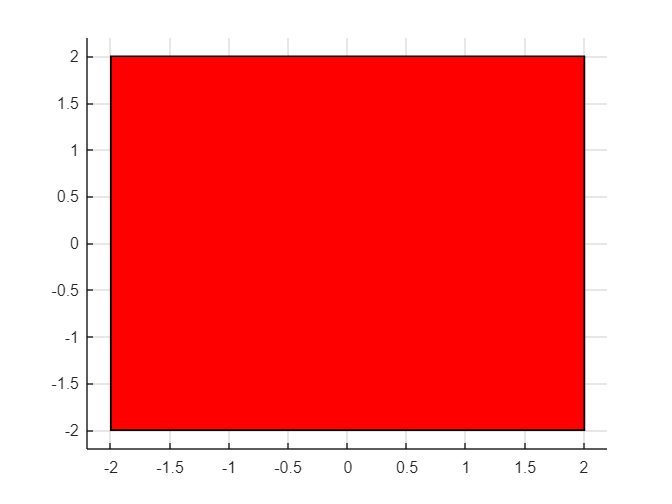

figure(1)
plot(P)

Q=Polyhedron(A2,b2)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   4 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


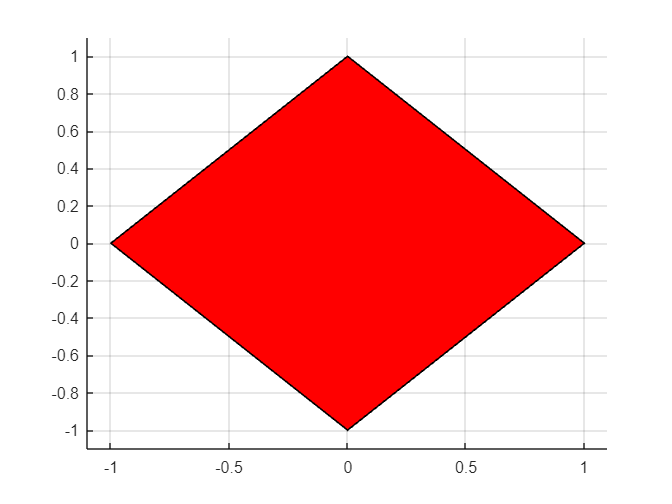

figure(2)
plot(Q)

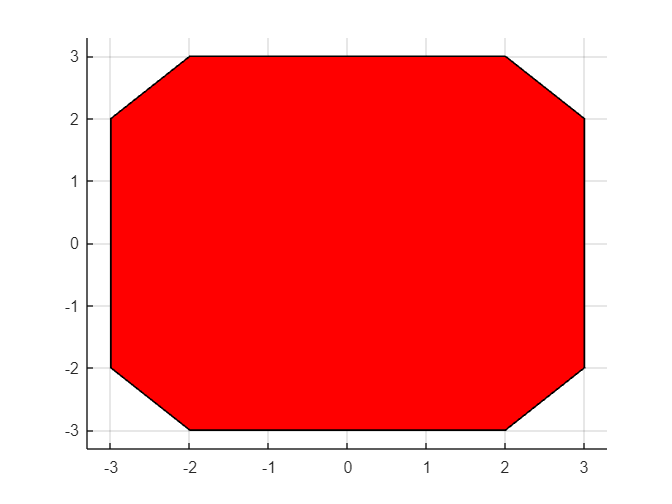

figure(3)
plot(P+Q)

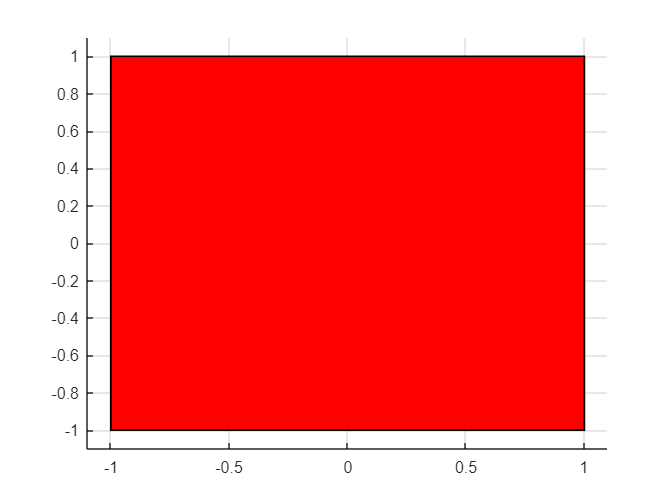

figure(4)
plot(P-Q)

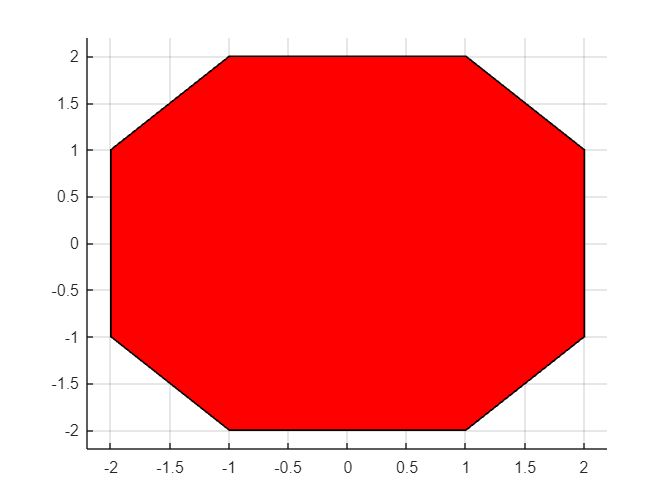

figure(5)
plot(P-Q+Q)

figure(6)
plot((P+Q)-Q)

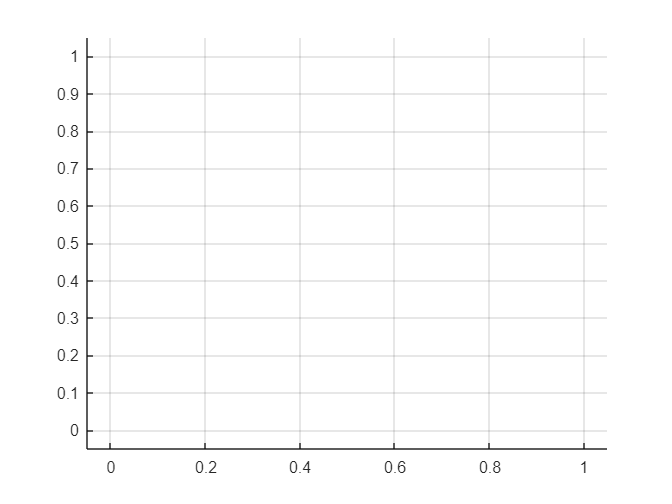

figure(7)
plot((Q-P))

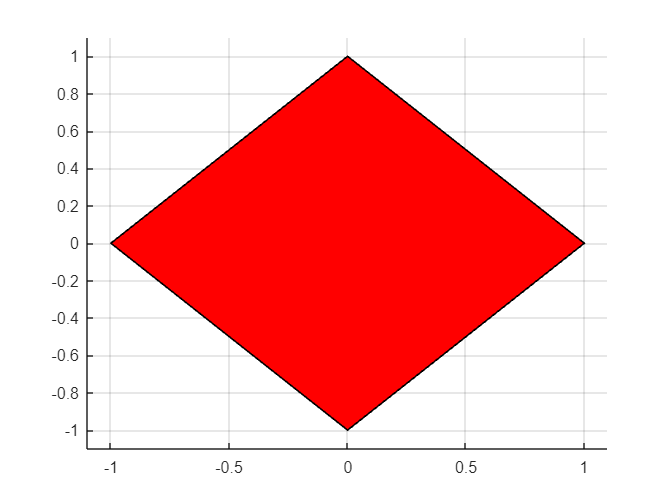

figure(8)
plot((Q+P)-P)

%question 2
%(a)
A=[0.8 0.4;-0.4 0.8];
Ain=[1 0;0 1;-1 0;0 -1;1 1;1 -1;-1 1;-1 -1];
bin=[ones(4,1);1.5*ones(4,1)];
X_a=Polyhedron(Ain,bin);
XX_a=A*X_a

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   8 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


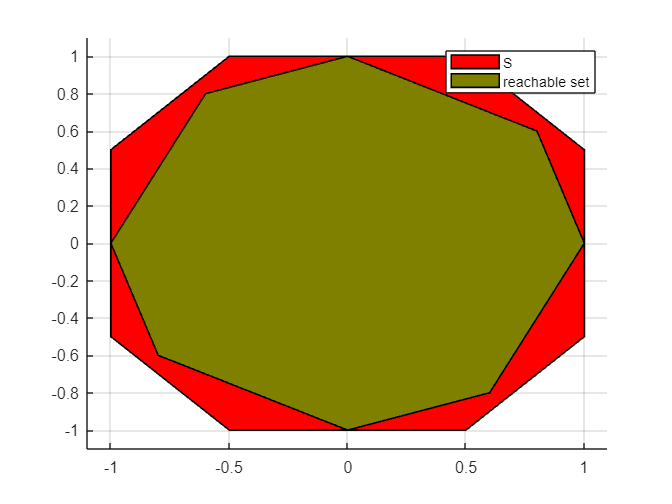

plot(X_a,'color','red',XX_a,'color','olive')
legend('S','reachable set')

%(b)
A=[0.8 0.4;-0.4 0.8];
B=[0 1]';
u_b=Polyhedron('lb',-1,'ub',1)

Polyhedron in R^1 with representations:
    H-rep (redundant)   : Inequalities   2 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


X_b=Polyhedron(Ain,bin);
XX_b=A*X_b+B*u_b

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  10 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


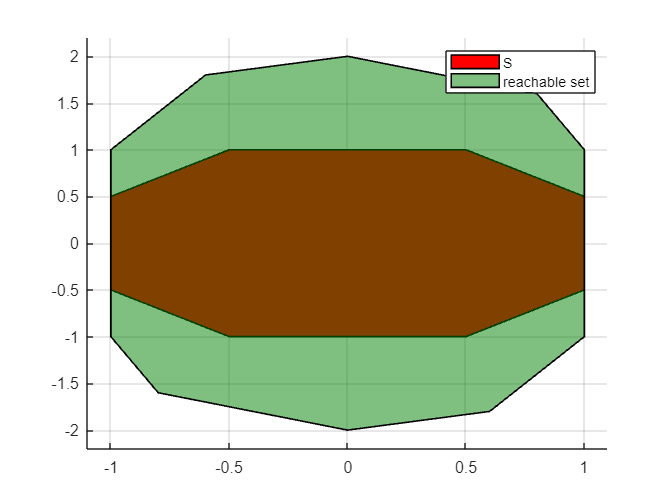

plot(X_b,'color','red',XX_b,'color','green','alpha',0.5)
legend('S','reachable set')

%(c)

T=Polyhedron('A',[Ain*A Ain*B;zeros(2,2) u_b.A],'b',[bin;u_b.b])

Polyhedron in R^3 with representations:
    H-rep (redundant)   : Inequalities  10 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


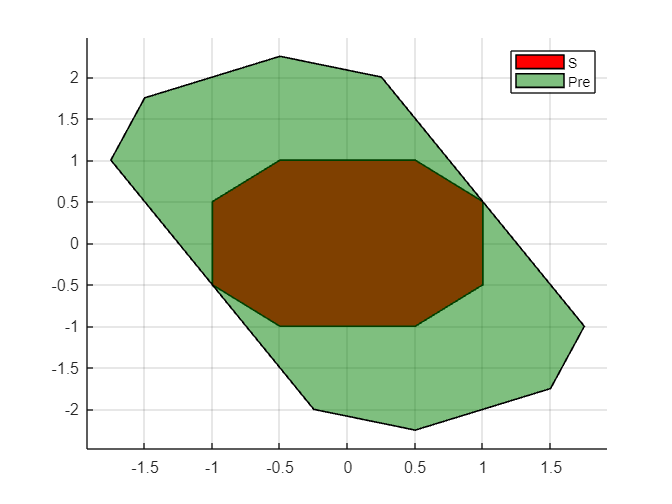

Projection=T.projection(1:2);
plot(X_b,'color','red',Projection,'color','green','alpha',0.5)
legend('S','Pre')



model=LTISystem('A',A,'B',B)

LTISystem with 2 states, 1 input, 0 outputs


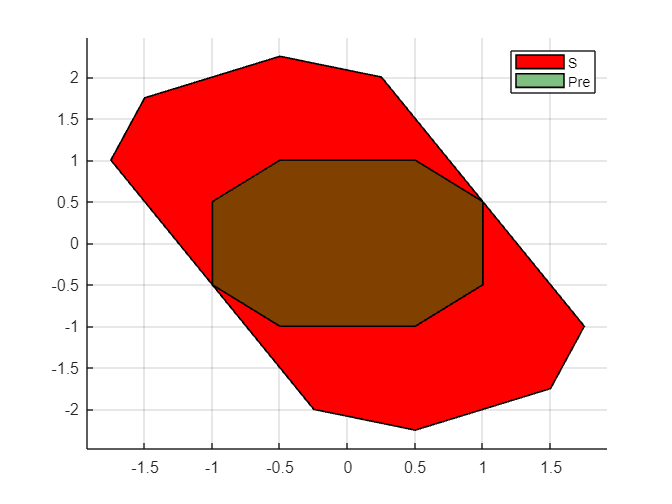

Xpre = model.reachableSet('X', X_b, 'U', u_b, 'direction', 'backward','N',1);
XpreandX = Xpre.intersect(X_b).minHRep();
plot(Xpre,'color','red',XpreandX,'color','green','alpha',0.5)
legend('S','Pre')

%question 3
%(a)
clc
clear all
A=[0.9 0.4;-0.4 0.9];
B=[0;1];
Ain=[1 0;-1 0;0 1;0 -1];
bin=3*ones(4,1);
Q=eye(2);R=1;pf=0;
X_c=Polyhedron(Ain,bin)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   4 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


u_c=Polyhedron('lb',-0.1,'ub',0.1);
x0=[2;0];
xf=Polyhedron([0 0]);
model_c=LTISystem('A',A,'B',B)

LTISystem with 2 states, 1 input, 0 outputs


model_c.u.min = -0.1;
model_c.u.max = 0.1;
model_c.x.min = [-3;-3];
model_c.x.max = [3;3];
model_c.x.penalty = QuadFunction(Q);
model_c.u.penalty = QuadFunction(R);
model_c.x.with('terminalPenalty');
model_c.x.terminalPenalty=QuadFunction(zeros(2,2));
model_c.x.with('terminalSet');
model_c.x.terminalSet =xf;
count=1

count = 1


while true
    xf=model_c.reachableSet('X',xf,'U',u_c,'direction', 'backward','N',1);
    xf = xf.intersect(X_c).minHRep();
    if xf.contains(x0)
        break
    end
    count=count+1;
end
disp(count)

    26



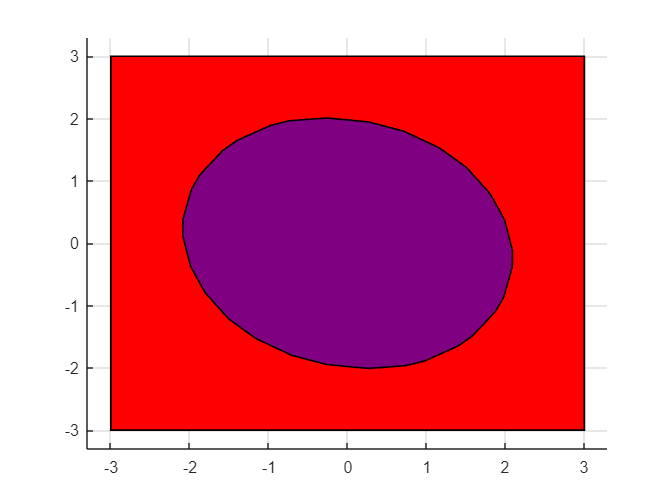

plot(X_c,xf,'color','blue','alpha',0.5);

%(b)
N=2

N = 2

Cinf=Polyhedron([0 0]);
Cinf_sys = model_c.invariantSet(); 

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...


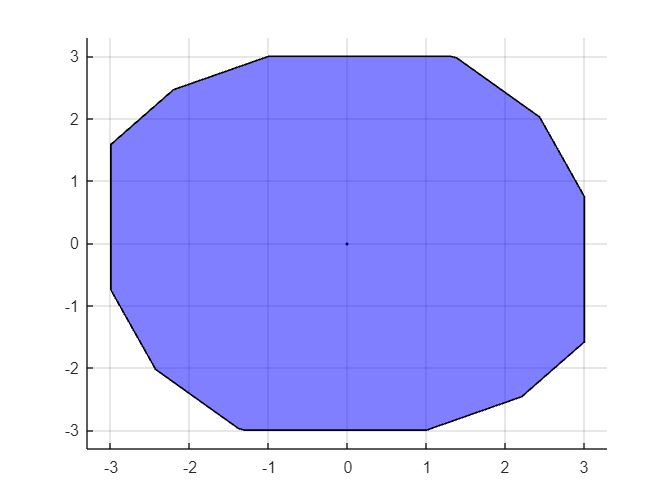


model_c.x.terminalSet =Cinf_sys;
plot(Cinf,Cinf_sys,'color','blue','alpha',0.5);

mpc=MPCController(model_c,N);
[~, feasible, ~] = mpc.evaluate(x0)

feasible = logical
   1


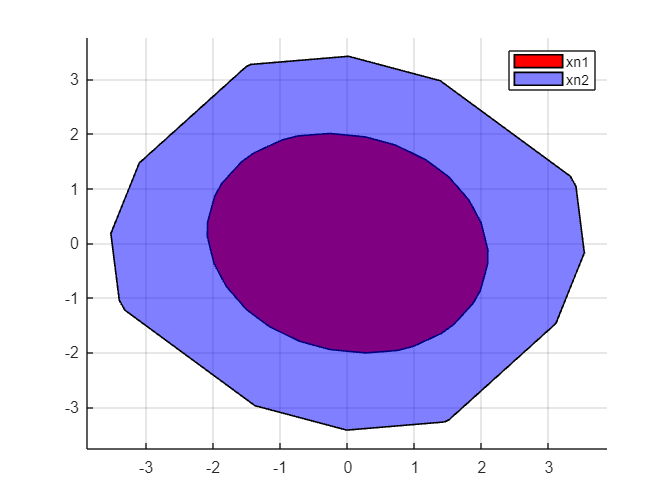

%(c)
xf2=model_c.reachableSet('X',Cinf_sys,'U',u_c,'direction', 'backward','N',2);
plot(xf,xf2,'color','blue','alpha',0.5);
legend('xn1','xn2')

xf

Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities  52 | Equalities   0
    V-rep (irredundant) : Vertices  52 | Rays   0
Functions : none


xf2

Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities  16 | Equalities   0
    V-rep (irredundant) : Vertices  16 | Rays   0
Functions : none
